%%%%%
% SCRIPT TO PLOT DEPTH OF TUNING DURING LEARNING
%%%%%
clear; clc; close all;
dataSummary;

% set parameters
keepResults = {'R'};
spikeWindow = {'idx_go_cue',-10; 'idx_peak_speed',-10};
min_fr = 5;
alpha = 0.01;

monkey_dot = cell(1,2);

filenames = { ...
    'Chewie_CO_FF_2013-10-22', ...
    'Chewie_CO_FF_2013-10-23', ...
    'Chewie_CO_FF_2013-10-31', ...
    'Chewie_CO_FF_2013-11-01', ...
    'Chewie_CO_FF_2013-12-03', ...
    'Chewie_CO_FF_2013-12-04', ...
    'Chewie_CO_FF_2015-07-01', ...
    'Chewie_CO_FF_2015-07-03', ...
    'Chewie_CO_FF_2015-06-29', ...
    'Chewie_CO_FF_2015-06-30', ...
    'Chewie_CO_FF_2015-07-06', ...
    'Chewie_CO_FF_2015-07-07', ...
    'Chewie_CO_FF_2015-07-08', ...
    };


all_dot = [];
for iFile = 1:length(filenames)
    % load data
    filepath = fullfile(rootDir,TDDir,[filenames{iFile} '.mat']);
    td=load(filepath);
    td = td.trial_data;
    
    for trial = 1:length(td)
        td(trial).target_direction = binAngles(td(trial).target_direction,pi/4);
        if td(trial).target_direction < -2.5
            td(trial).target_direction = -td(trial).target_direction;
        end
    end
    
    utheta = unique([td.target_direction]);
    
    % filter data
    if isfield(td,'result'), td = td(getTDidx(td,'result',keepResults)); end
    
    % firing rates for all trials
    fr = zeros(size(td(1).M1_spikes,2),length(td));
    for trial = 1:length(td)
        idx = td(trial).(spikeWindow{1,1})+spikeWindow{1,2}:td(trial).(spikeWindow{2,1})+spikeWindow{2,2};
        fr(:,trial) = 100*sum(td(trial).M1_spikes(idx,:),1)/length(idx);
    end
    
    idx = find(getTDidx(td,'epoch','BL'));
    p = zeros(size(fr,1),1);
    for i = 1:size(fr,1)
        p(i) = anovan(fr(i,idx)',[td(idx).target_direction]','Display','off');
    end
    good_cells = mean(fr(:,idx),2) > min_fr & p < alpha;
    
    fr = fr(good_cells,:);
    
    file_dot = zeros(size(fr,1),7);
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','BL','target_direction',utheta(theta)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,1) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','AD','target_direction',utheta(theta)));
        idx = idx(1:floor(0.33*length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,2) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','AD','target_direction',utheta(theta)));
        if isempty(idx)
            fr_dir(:,theta) = NaN;
        else
            idx = idx(ceil(0.33*length(idx)):floor(0.66*length(idx)));
            fr_dir(:,theta) = mean(fr(:,idx),2);
        end
    end
    
    file_dot(:,3) = max(fr_dir') - min(fr_dir');
    
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','AD','target_direction',utheta(theta)));
        if isempty(idx)
            fr_dir(:,theta) = NaN;
        else
            idx = idx(ceil(0.66*length(idx)):floor(length(idx)));
            fr_dir(:,theta) = mean(fr(:,idx),2);
        end
    end
    
    file_dot(:,4) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','WO','target_direction',utheta(theta)));
        idx = idx(1:floor(0.33*length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,5) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','WO','target_direction',utheta(theta)));
        idx = idx(ceil(0.33*length(idx)):floor(0.66*length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,6) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','WO','target_direction',utheta(theta)));
        idx = idx(ceil(0.66*length(idx)):floor(length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,7) = max(fr_dir') - min(fr_dir');
    
    all_dot = [all_dot; file_dot];
end

monkey_dot{1} = all_dot;




filenames = { ...
    'Mihili_CO_FF_2014-02-03', ...
    'Mihili_CO_FF_2014-02-17', ...
    'Mihili_CO_FF_2014-02-18', ...
    'Mihili_CO_FF_2014-03-07', ...
    'Mihili_CO_FF_2015-06-11', ...
    'Mihili_CO_FF_2015-06-17', ...
    'Mihili_CO_FF_2015-06-10', ...
    'Mihili_CO_FF_2015-06-15', ...
    'Mihili_CO_FF_2015-06-16', ...
    };

all_dot = [];
for iFile = 1:length(filenames)
    % load data
    filepath = fullfile(rootDir,TDDir,[filenames{iFile} '.mat']);
    td=load(filepath);
    td = td.trial_data;
    
    for trial = 1:length(td)
        td(trial).target_direction = binAngles(td(trial).target_direction,pi/4);
        if td(trial).target_direction < -2.5
            td(trial).target_direction = -td(trial).target_direction;
        end
    end
    
    utheta = unique([td.target_direction]);
    
    % filter data
    if isfield(td,'result'), td = td(getTDidx(td,'result',keepResults)); end
    
    
    
    % firing rates for all trials
    fr = zeros(size(td(1).M1_spikes,2),length(td));
    for trial = 1:length(td)
        idx = td(trial).(spikeWindow{1,1})+spikeWindow{1,2}:td(trial).(spikeWindow{2,1})+spikeWindow{2,2};
        fr(:,trial) = 100*sum(td(trial).M1_spikes(idx,:),1)/length(idx);
    end
    
    idx = find(getTDidx(td,'epoch','BL'));
    p = zeros(size(fr,1),1);
    for i = 1:size(fr,1)
        p(i) = anovan(fr(i,idx)',[td(idx).target_direction]','Display','off');
    end
    good_cells = mean(fr(:,idx),2) > min_fr & p < alpha;
    
    fr = fr(good_cells,:);
    
    file_dot = zeros(size(fr,1),7);
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','BL','target_direction',utheta(theta)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,1) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','AD','target_direction',utheta(theta)));
        idx = idx(1:floor(0.33*length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,2) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','AD','target_direction',utheta(theta)));
        if isempty(idx)
            fr_dir(:,theta) = NaN;
        else
            idx = idx(ceil(0.33*length(idx)):floor(0.66*length(idx)));
            fr_dir(:,theta) = mean(fr(:,idx),2);
        end
    end
    
    file_dot(:,3) = max(fr_dir') - min(fr_dir');
    
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','AD','target_direction',utheta(theta)));
        if isempty(idx)
            fr_dir(:,theta) = NaN;
        else
            idx = idx(ceil(0.66*length(idx)):floor(length(idx)));
            fr_dir(:,theta) = mean(fr(:,idx),2);
        end
    end
    
    file_dot(:,4) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','WO','target_direction',utheta(theta)));
        idx = idx(1:floor(0.33*length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,5) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','WO','target_direction',utheta(theta)));
        idx = idx(ceil(0.33*length(idx)):floor(0.66*length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,6) = max(fr_dir') - min(fr_dir');
    
    % get baseline firing rates
    fr_dir = zeros(size(fr,1),length(utheta));
    for theta = 1:length(utheta)
        idx = find(getTDidx(td,'epoch','WO','target_direction',utheta(theta)));
        idx = idx(ceil(0.66*length(idx)):floor(length(idx)));
        fr_dir(:,theta) = mean(fr(:,idx),2);
    end
    
    file_dot(:,7) = max(fr_dir') - min(fr_dir');
    
    all_dot = [all_dot; file_dot];
end

monkey_dot{2} = all_dot;


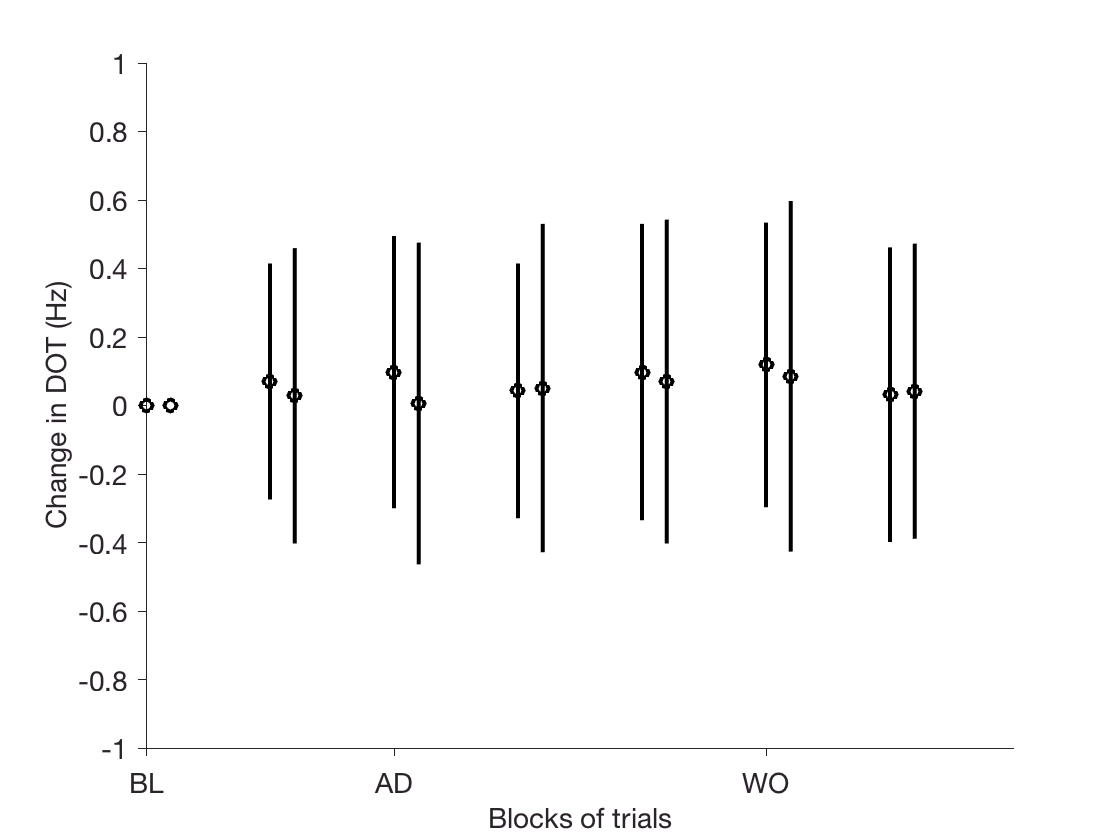

figure; hold all;

for i = 1:2
    all_dot = monkey_dot{i};
    
    temp = 1;%sqrt(size(all_dot,1));
    
    d_dot = (all_dot - repmat(all_dot(:,1),1,7))./repmat(all_dot(:,1),1,7);
    m = nanmean(d_dot,1);
    s = [m-nanstd(d_dot,1)/temp; m+nanstd(d_dot,1)/temp];
    %s(:,1) = [nanstd(all_dot(:,1))/temp,-nanstd(all_dot(:,1))/temp]/mean(all_dot(:,1),1)
    
    % s = prctile(d_dot,[2.5,97.5]);
    plot([1:7;1:7]+0.2*(i-1),s,'k','LineWidth',2);
    plot((1:7)+0.2*(i-1),m,'ko','LineWidth',2);
end

set(gca,'Box','off','TickDir','out','FontSize',14,'YLim',[-1 1],'XTick',[1,3,6],'XTickLabel',{'BL','AD','WO'});
ylabel('Change in DOT (Hz)','FontSize',14);
xlabel('Blocks of trials','FontSize',14);